% This file contains a minimum working example demonstrating the use of the
% MATLAB distribution of SE-Sync, a certifiably correct algorithm for 
% synchronization over the special Euclidean group
%
% Copyright (C) 2016 by David M. Rosen

## Reset environment

clear all;
close all;
clc;

## Import SE-Sync

run('../import_SE_Sync.m');  % It's that easy :-)!

Manopt was added to Matlab's path.
Path saved: no need to call importmanopt next time.


## Select dataset to run

data_dir = '../../data/';  % Relative path to directory containing example datasets

% 3D datasets
sphere2500 = 'sphere2500';
torus = 'torus3D';
grid = 'grid3D';
garage = 'parking-garage';
cubicle = 'cubicle';
rim = 'rim';

% 2D datasets
CSAIL = 'CSAIL';
manhattan = 'manhattan';
city10000 = 'city10000';
intel = 'intel';
ais = 'ais2klinik';


% Pick the dataset to run here
file = garage;

g2o_file = strcat(data_dir, file, '.g2o');

## Read in .g2o file

tic();
fprintf('Loading file: %s ...\n', g2o_file);

Loading file: ../../data/parking-garage.g2o ...


measurements = load_g2o_data(g2o_file);  
t = toc();
num_poses = max(max(measurements.edges));
num_measurements = length(measurements.kappa);
d = length(measurements.t{1});
fprintf('Processed input file %s in %g seconds\n', g2o_file, t);

Processed input file ../../data/parking-garage.g2o in 0.495537 seconds


fprintf('Number of poses: %d\n', num_poses);

Number of poses: 1661


fprintf('Number of measurements: %d\n', num_measurements);

Number of measurements: 6275


## Set Manopt options (if desired)

Manopt_opts.tolgradnorm = 1e-2;  % Stopping tolerance for norm of Riemannian gradient
Manopt_opts.rel_func_tol = 1e-5;  % Additional stopping criterion for Manopt: stop if the relative function decrease between two successive accepted iterates is less than this value
Manopt_opts.miniter = 1;  % Minimum number of outer iterations (i.e. accepted update steps) to perform
Manopt_opts.maxiter = 300;  % Maximum number of outer iterations (i.e. accepted update steps) to perform
Manopt_opts.maxinner = 500;  % Maximum number of iterations for the conjugate-gradient method used to compute approximate Newton steps
%manopt_options.maxtime = 60*60;  % Maximum computation time to allow, in seconds
%manopt_options.solver = @steepestdescent;  % Select Manopt solver to use: {trustregions (default), conjugategradient, steepestdescent}

## Set SE-Sync options (if desired)

SE_Sync_opts.r0 = 5;  % Initial maximum-rank parameter at which to start the Riemannian Staircase
SE_Sync_opts.rmax = 10;  % Maximum maximum-rank parameter at which to terminate the Riemannian Staircase
SE_Sync_opts.eig_comp_rel_tol = 1e-4;  % Relative tolerance for the minimum-eigenvalue computation used to test for second-order optimality with MATLAB's eigs() function
SE_Sync_opts.min_eig_lower_bound = -1e-3;  % Minimum eigenvalue threshold for accepting a maxtrix as numerically positive-semidefinite
SE_Sync_opts.Cholesky = false;  % Select whether to use Cholesky or QR decomposition to compute orthogonal projections

use_chordal_initialization = true;  % Select whether to use the chordal initialization, or a random starting point

## Run SE-Sync

% Pass explict settings for SE-Sync and/or Manopt, and use chordal
% initialization
fprintf('Computing chordal initialization...\n');

Computing chordal initialization...


R = chordal_initialization(measurements);
Y0 = vertcat(R, zeros(SE_Sync_opts.r0 - d, num_poses*d));
[SDPval, Yopt, xhat, Fxhat, SE_Sync_info, problem_data] = SE_Sync(measurements, Manopt_opts, SE_Sync_opts, Y0);



========== SE-Sync ==========

ALGORITHM SETTINGS:

SE-Sync settings:
 Initial level of Riemannian Staircase: 5
 Final level of Riemannian Staircase: 10
 Maximum number of iterations to perform for minimum eigenvalue computation in test for positive semidefiniteness: 2000 [default]
 Tolerance for accepting an eigenvalue as numerically nonnegative in optimality verification: 0.0001 [default]
 Using QR decomposition to compute orthogonal projection
 Initialization method: chordal [default]

Manopt settings:
 Stopping tolerance for norm of Riemannian gradient: 0.01
 Stopping tolerance for relative function decrease: 1e-05
 Maximum number of Hessian-vector products to evaluate in each truncated Newton iteration: 500
 Minimum number of trust-region iterations: 1
 Maximum number of trust-region iterations: 300
 Using incomplete zero-fill Cholesky preconditioner for truncated conjugate gradient inexact Newton step computations [default]


INITIALIZATION:

Constructing auxiliary data matrice

Elapsed computation time: 0.014718 seconds

Value of SDP solution F(Y): 1.26253
Norm of Riemannian gradient grad F(Y): 0.00310168
Value of rounded pose estimate xhat: 1.26253
Suboptimality bound of recovered pose estimate: -4.46776e-12

Total elapsed computation time: 4.83816 seconds


===== END SE-SYNC =====



% ... or ...

% Use default settings for everything
%[SDPval, Yopt, xhat, Fxhat, se_sync_info, problem_data] = SE_Sync(measurements);

## Plot resulting solution

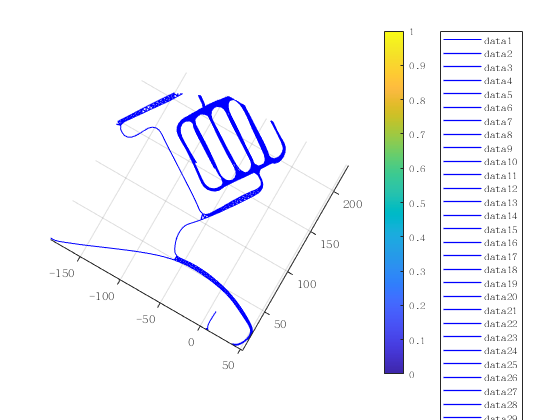

plot_loop_closures = true;

if plot_loop_closures
    plot_poses(xhat.t, xhat.R, measurements.edges, '-b', .25);
else
    plot_poses(xhat.t, xhat.R);
end
axis tight;


%view(90, -90);  % For plotting 3D but nearly-planar datasets